# Illustrate sensor aliasing

Problems arise when a lens  renders a very fine pattern that exceeds the Nyquist sampling rate of the sensor. In that case the sensor outputs will be incorrectly interpreted, usually as a relatively coarse pattern. The apparently coarse pattern is called an alias: it appears to be vary slowly across space even though the original image varies rapidly. 

- We first illustrate aliasing in a simple case of a monochrome sensor.

- Then we consider the aliasing pattern when we use a color filter array. 

To prevent  aliasing, we choose lenses that do not pass high frequency patterns that exceed the Nyquist sampling rate of the sensor. This was common in the early days of digital imaging, and manufacturers often included a special blurring filter that would prevent aliasing.

When the sensor sampling rate is very high, say  high enough rate to sample even a diffraction-limited lens, there is no need to use an anti-aliasing filter.  That is the direction that the industry now has taken.  

**See also:**  hwSensorAliasing, s_sensorAliasing

ieInit

## Set up a high frequency harmonic

fov = 1;
hParams = harmonicP;
hParams.freq = 8;
hParams.row = 128; hParams.col = 256;
scene = sceneCreate('harmonic',hParams);
scene = sceneSet(scene,'fov',fov);
sceneWindow(scene);

% Set up a high quality lens
oi = oiCreate('diffraction limited');
oi = oiSet(oi,'optics fnumber', 2);
oi = oiCompute(oi,scene);
oiWindow(oi);

## We use a small (1 $um$) pixel

sensor = sensorCreate('monochrome');
sensor = sensorSetSizeToFOV(sensor,3*fov,oi);

sensor = sensorSet(sensor,'pixel size constant fill factor',1e-6);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

% Plot a middle row
middleRow = round(sensorGet(sensor,'row')/2);
sensorPlot(sensor,'electrons hline',[1 middleRow]);

## Use a bigger pixel (6 $um$)

The aliased signal is plotted on the right.  The scene and oi are high spatial frequency, but the sensor data appears to correspond to a low spatial frequency.

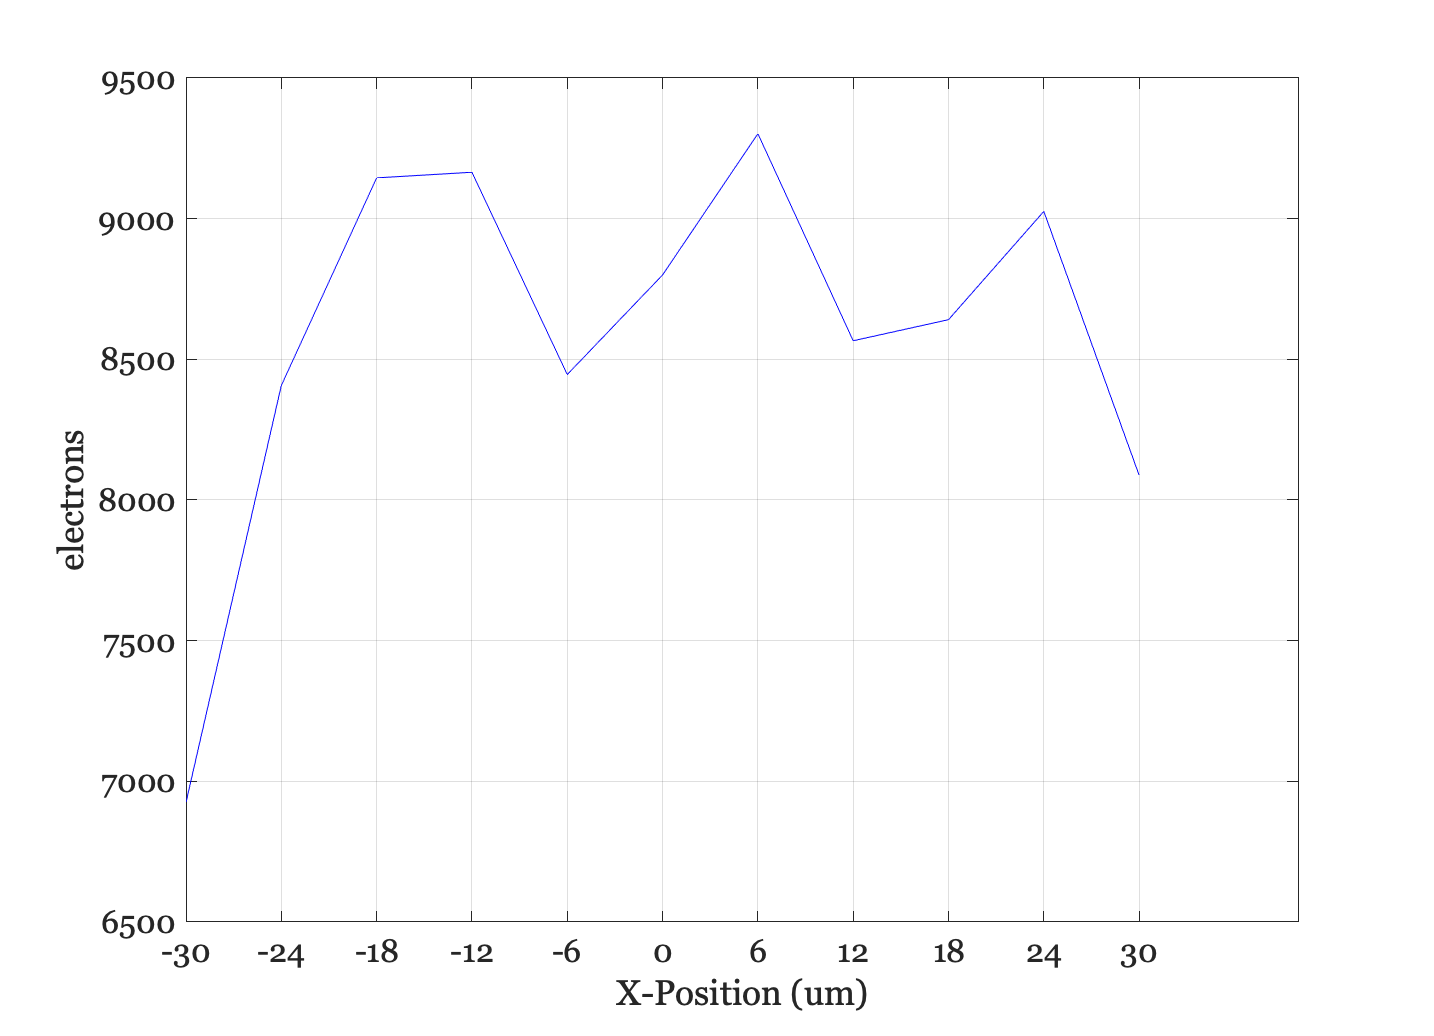

sensor = sensorSet(sensor,'pixel size constant fill factor',6e-6);
sensor = sensorSetSizeToFOV(sensor,fov,oi);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

middleRow = round(sensorGet(sensor,'row')/2);
sensorPlot(sensor,'electrons hline',[1 middleRow]);

## Now, reduce aliasing by using a blurry lens

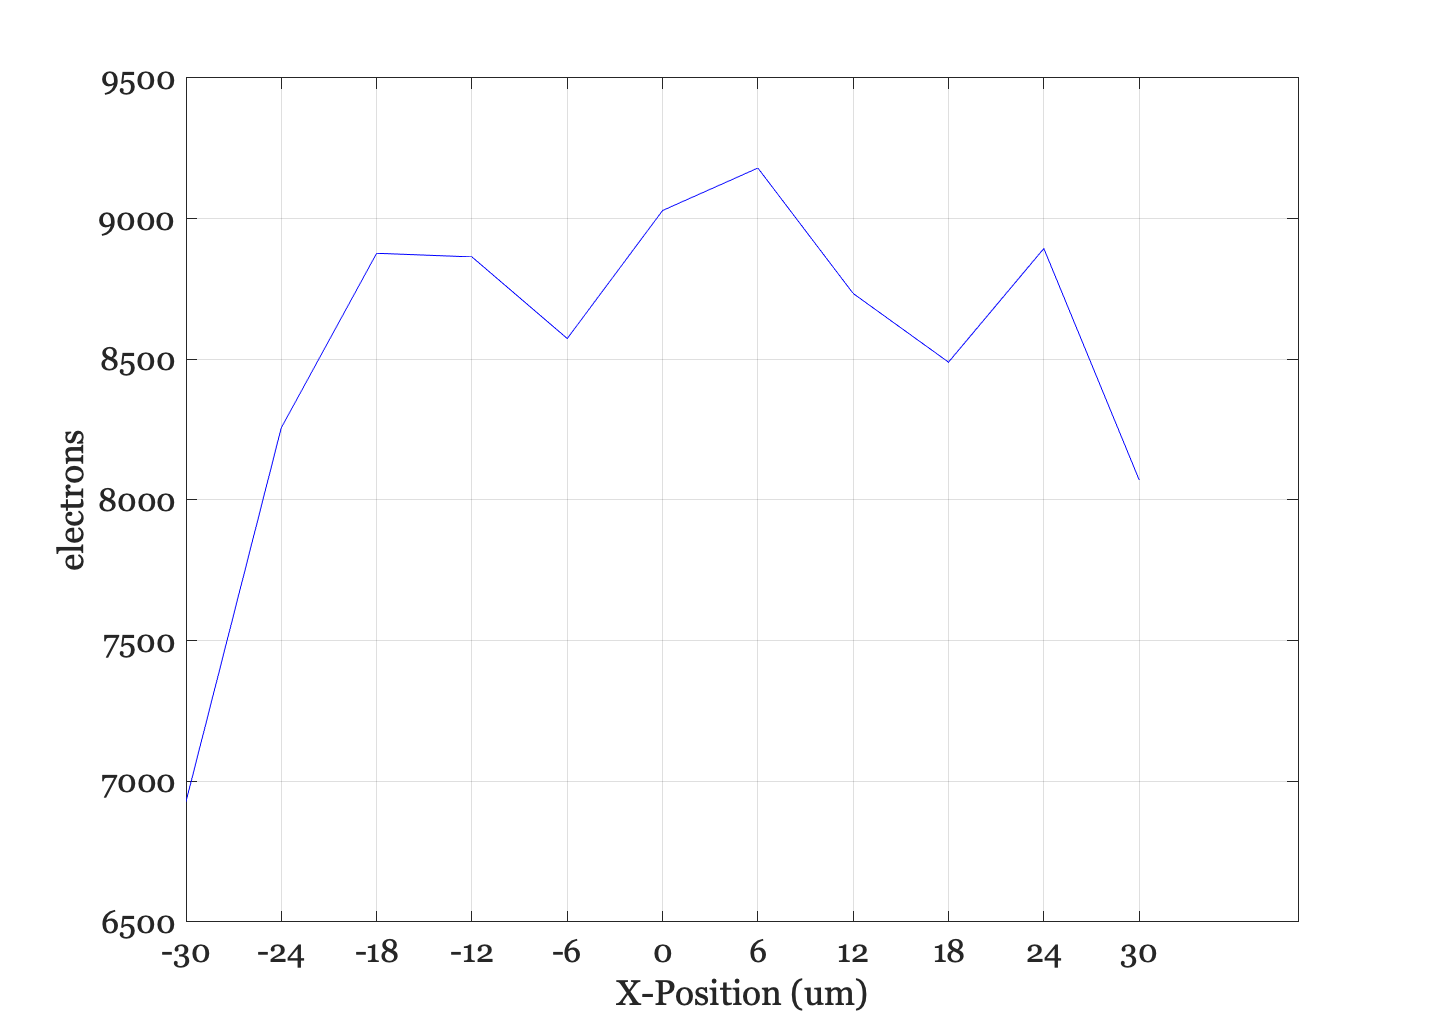

oi = oiSet(oi,'optics fnumber', 14);
oi = oiCompute(oi,scene);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

middleRow = round(sensorGet(sensor,'row')/2);
sensorPlot(sensor,'electrons hline',[1 middleRow]);

## Let's use a different pattern

scene = sceneCreate('freqorient',[512 512]);
oi = oiSet(oi,'optics fnumber', 2);
oi = oiCompute(oi,scene);
oiWindow(oi);

## Adding the impact of a color filter array (1 $um$)

sensor = sensorCreate;
sensor = sensorSet(sensor,'pixel size constant fill factor',1e-6);
sensor = sensorSetSizeToFOV(sensor,sceneGet(scene,'fov'),oi);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

ip = ipCreate; ip = ipCompute(ip,sensor);
ipWindow(ip);

## A CFA with 6 $um$pixels

sensor = sensorSet(sensor,'pixel size constant fill factor',6e-6);
sensor = sensorSetSizeToFOV(sensor,sceneGet(scene,'fov'),oi);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

ip = ipCreate; ip = ipCompute(ip,sensor);
ipWindow(ip);